## raw数据离线测试

clc;clear all;close all;
location = 'test/';
% for name = 1:1:9
file = '4';
% file = num2str(name);
filename = [location, file, '.dat'];
savename = ['mergedData', '_', file, '.mat'];
p = setRadarParameters();
frameIdx = 0;
% 读取全部数据
if exist([location, savename], 'file')
    disp('文件已存在。');
    load([location, savename]);
else
    disp('文件不存在，开始读取。');
    rdr = RadarFrameReader(filename, p.Chirps);
    rx0 = {};
    rx1 = {};
    while true
        [rx0Data,rx1Data,chirpIds,hasMore] = rdr.readFrame();
        frameIdx = frameIdx + 1;
        fprintf("\r已读取第 %d 帧",frameIdx);

        %数据拼接
        rx0 = vertcat(rx0,rx0Data);
        rx1 = vertcat(rx1,rx1Data);
        if ~hasMore, break; end
    end
    fprintf('\n总共读取了 %d 帧数据\n', frameIdx);
    mergedData = mergeCells(rx0, rx1);
    save([location, savename], 'mergedData', '-v7.3');% 保存数据
end

文件不存在，开始读取。


文件: test/4.dat  已打开 (0.026 GB)



已读取第 1 帧
已读取第 2 帧
已读取第 3 帧
已读取第 4 帧
已读取第 5 帧
已读取第 6 帧
已读取第 7 帧
已读取第 8 帧
已读取第 9 帧
已读取第 10 帧
已读取第 11 帧
已读取第 12 帧
已读取第 13 帧
已读取第 14 帧
已读取第 15 帧
已读取第 16 帧
已读取第 17 帧
已读取第 18 帧
已读取第 19 帧
已读取第 20 帧
已读取第 21 帧
已读取第 22 帧
已读取第 23 帧
已读取第 24 帧
已读取第 25 帧
已读取第 26 帧
已读取第 27 帧
已读取第 28 帧
已读取第 29 帧
已读取第 30 帧
已读取第 31 帧
已读取第 32 帧
已读取第 33 帧
已读取第 34 帧
已读取第 35 帧
已读取第 36 帧
已读取第 37 帧
已读取第 38 帧
已读取第 39 帧
已读取第 40 帧
已读取第 41 帧
已读取第 42 帧
已读取第 43 帧
已读取第 44 帧
已读取第 45 帧
已读取第 46 帧
已读取第 47 帧
已读取第 48 帧
已读取第 49 帧
已读取第 50 帧
已读取第 51 帧
已读取第 52 帧
已读取第 53 帧
已读取第 54 帧
已读取第 55 帧
已读取第 56 帧
已读取第 57 帧
已读取第 58 帧
已读取第 59 帧
已读取第 60 帧
已读取第 61 帧
已读取第 62 帧
已读取第 63 帧
已读取第 64 帧
已读取第 65 帧
已读取第 66 帧
已读取第 67 帧
已读取第 68 帧
已读取第 69 帧
已读取第 70 帧
已读取第 71 帧
已读取第 72 帧
已读取第 73 帧
已读取第 74 帧
已读取第 75 帧
已读取第 76 帧
已读取第 77 帧
已读取第 78 帧
已读取第 79 帧
已读取第 80 帧
已读取第 81 帧
已读取第 82 帧
已读取第 83 帧
已读取第 84 帧
已读取第 85 帧
已读取第 86 帧
已读取第 87 帧
已读取第 88 帧
已读取第 89 帧
已读取第 90 帧
已读取第 91 帧
已读取第 92 帧
已读取第 93 帧
已读取第 94 帧
已读取第 95 帧
已读取第 96 帧
已读取第 97 帧
已读取第 98 帧
已读取第 99 帧
已读取第 100 帧
已读取第 10


总共读取了 205 帧数据


disp('读取完毕。');

读取完毕。


[FrameNum, ChirpNum, RxNum, SampleNum] = size(mergedData);

a = tic;
tic;
% 初始参数
axis_info = setaxis(p);
axis_info.time = (1:FrameNum) * p.frameTime; 
% 裁剪
UsefulSampleNum = find(axis_info.range>p.rangecut, 1);
axis_info.range(UsefulSampleNum:end) = [];
UsefulChirpNumF = find(axis_info.velocity<-p.velocitycut, 1, 'last');
UsefulChirpNumL = find(axis_info.velocity>p.velocitycut, 1, "first");
axis_info.velocity([1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft]) = [];
disp(['axis:', num2str(toc/FrameNum*1e3)]);

axis:0.1361


tic;

% 1dfft
fft1dData = fft1dwindow(mergedData, p.fft1dwindowType, p.Nfft);

1dfft done.


fft1dData(:,:,:,UsefulSampleNum:end) = [];
disp(['1dfft:', num2str(toc/FrameNum*1e3)]);

1dfft:1.9795


tic;
% MTI
MTIdata = MTI(fft1dData, p.MTIType);

Mean Cancellation done.


disp(['MTI:', num2str(toc/FrameNum*1e3)]);

MTI:0.095196


tic;
% 2dfft
fft2dData = fft2dwindow(MTIdata, p.fft2dwindowType, p.Nfft);

2dfft done.


fft2dData(:,[1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft],:,:) = [];
disp(['2dfft:', num2str(toc/FrameNum*1e3)]);

2dfft:0.75161


tic;
% NCA
NCAdata = squeeze(sum(fft2dData, 3));
disp(['NCA:', num2str(toc/FrameNum*1e3)]);

NCA:0.11032


tic;
% AAC
AACdata = applyAmplitudeCompensation(NCAdata);

AAC done.


disp(['AAC:', num2str(toc/FrameNum*1e3)]);

AAC:0.61677


tic;
% DN
lossR = 90;
lossD = 0;
DNdata = DenoisingRD(lossR, lossD, axis_info, AACdata);

Denoising done.


disp(['DN:', num2str(toc/FrameNum*1e3)]);

DN:0.25652


tic;
DNdata(:,:,1:6) = 1;

% CFAR
cfarIdx = processCFARDetection(p.N_target, p.suppressWin, p.energyThresh, p.epsilon, p.minPts, DNdata);
disp(['detection:', num2str(toc/FrameNum*1e3)]);

detection:2.7574


tic;

% DOA estimatematlab: opentoline('/Users/guojiaxiong/Documents/sync/MATLAB/FMCW_comp/func/estimateDoA.m',12,0)
DoA = estimateDoA(cfarIdx, p, fft2dData);
disp(['DoA:', num2str(toc/FrameNum*1e3)]);

DoA:2.0284


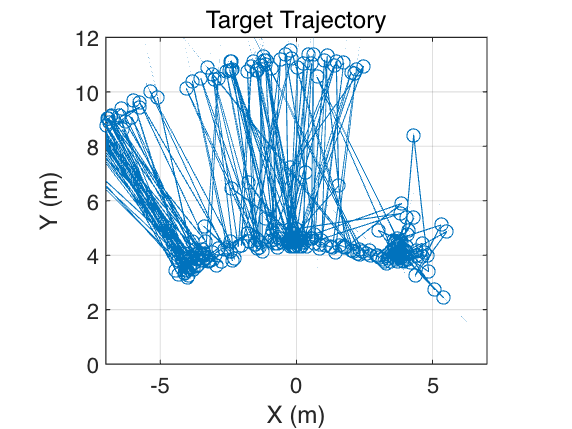

tic;
% Position modeling
observations = PositionModel(cfarIdx, axis_info, DoA(:, 2));

disp(['PositionModel:', num2str(toc/FrameNum*1e3)]);

PositionModel:1.9847


tic;

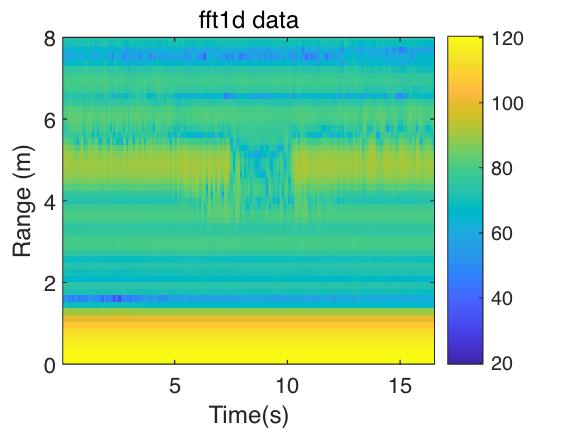

frameIdx = 35;

fft1dData_test = db(squeeze(fft1dData(:, 1, 1, :)));
plotRT(fft1dData_test, axis_info);title('fft1d data');

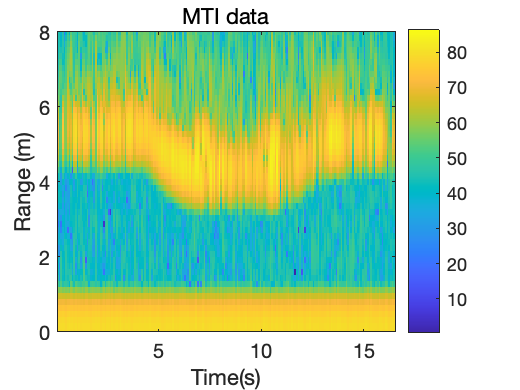


MTIdata_test = db(squeeze(MTIdata(:, 1, 1, :)));
plotRT(MTIdata_test, axis_info);title('MTI data');

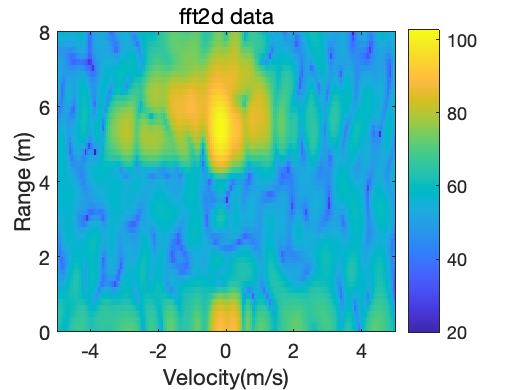

fft2dData_test = db(squeeze(fft2dData(frameIdx, :, 1, :)));
plotRV(fft2dData_test, axis_info);title('fft2d data');

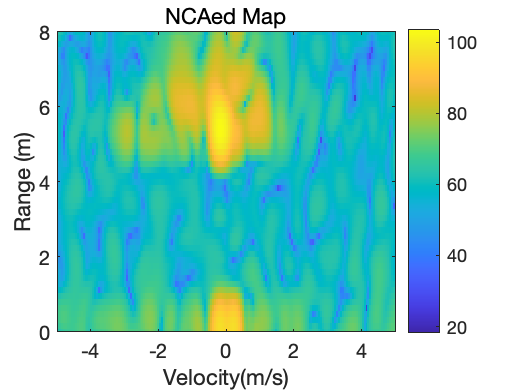


NCAdata_test = db(squeeze(NCAdata(frameIdx, :, :)));
plotRV(NCAdata_test, axis_info);title('NCAed Map');

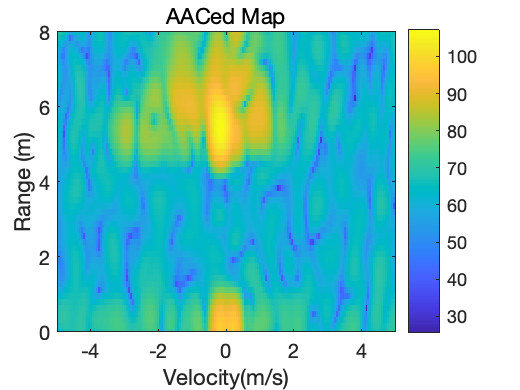


AACdata_test = db(squeeze(AACdata(frameIdx, :, :)));
plotRV(AACdata_test, axis_info);title('AACed Map');

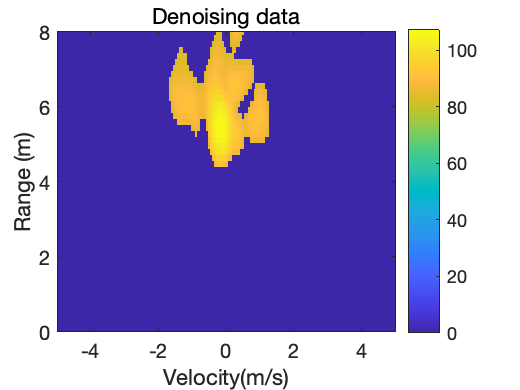


DNdata_test = db(squeeze(DNdata(frameIdx, :, :)));
plotRV(DNdata_test, axis_info);title('Denoising data');

%当前帧的轨迹点  current_points = [track_id  x  y ]
disp(['tracks:', num2str(toc/FrameNum*1e3)]);

tracks:27.1236


totaltime = toc(a)/FrameNum*1e3;
disp(['total:', num2str(totaltime)]);

total:38.1669


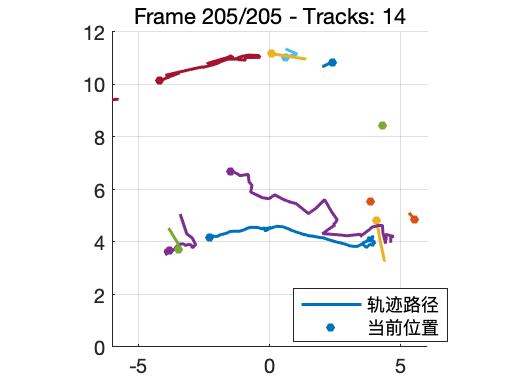

detections = cell(FrameNum, 1);
for k = 1:length(observations)
    idx = observations(k, 1);
    % 提取位置和速度 [x, y, vx, vy]
    pos_vel = [observations(k, 2), observations(k, 3), observations(k, 4)/10, observations(k, 5)/10];
    detections{idx} = [detections{idx}; pos_vel];
end

% 初始化图形窗口
figure;
axis equal;
grid on;
hold on;
xlim([-6 6]);ylim([0 12])
% 初始化轨迹历史容器
historyMap = containers.Map('KeyType', 'double', 'ValueType', 'any');
lineHandles = containers.Map('KeyType', 'double', 'ValueType', 'any'); % 存储线条句柄
pointHandles = containers.Map('KeyType', 'double', 'ValueType', 'any'); % 存储点句柄

% 设置颜色循环
colorOrder = get(gca, 'ColorOrder');
colorIndex = 1;

for i = 1:FrameNum
    % 更新轨迹点
    current_points = tracks_1f_plus(detections{i}, p.costThreshold, p.predictionframe, p.reset);
    
    % 更新轨迹历史并绘图
    for j = 1:size(current_points, 1)
        trackID = current_points(j, 1);
        position = current_points(j, 2:3);
        
        % 更新轨迹历史
        if isKey(historyMap, trackID)
            % 追加新位置
            historyMap(trackID) = [historyMap(trackID); position];
        else
            % 新建轨迹
            historyMap(trackID) = position;
            % 为新轨迹分配颜色
            lineHandles(trackID) = plot(NaN, NaN, ...
                'Color', colorOrder(colorIndex, :), ...
                'LineWidth', 1.5);
            pointHandles(trackID) = plot(NaN, NaN, 'o', ...
                'Color', colorOrder(colorIndex, :), ...
                'MarkerFaceColor', colorOrder(colorIndex, :), ...
                'MarkerSize', 4);
            
            % 更新颜色索引
            colorIndex = mod(colorIndex, size(colorOrder, 1)) + 1;
        end
        
        % 更新图形
        path = historyMap(trackID);
        set(lineHandles(trackID), 'XData', path(:,1), 'YData', path(:,2));
        set(pointHandles(trackID), 'XData', path(end,1), 'YData', path(end,2));
    end
    
    % 刷新图形
    title(sprintf('Frame %d/%d - Tracks: %d', i, FrameNum, historyMap.Count));
    drawnow;
    
    % 可选：控制帧率
    % pause(0.05); 
end

% 添加图例
legend('轨迹路径', '当前位置', 'Location', 'best');
hold off;